# Project #4

Carlos A. Sanchez

## Defining Problem Parameters and Domains

The following parameters define the heat solution problems at hand

clc, clear all;
%Defining Constants
N_r = 20;
N_z = N_r;
M_r = 3*N_r + 1;
M_z = 2*N_r + 1;
it_max = 100000;
R = 1;
H = 1.5;
Ts = 1;
Tb = 0.5;
delta_r = R/N_r;                %Sets delta_r value  
delta_z = H/N_z;                %Sets delta_z value
r = delta_r * 0:M_r - 1;
z = delta_z * 0:M_z - 1;
Error = 10^(-5);
lambda = 1.98;


## Setting up Preliminary Boundary Conditions

We now set the values for the padded area and bottom of the bracket mount

T = zeros(M_r,M_z);
T(1:M_r,1) = Tb;
T(1:N_r+1,N_z+1:M_z) = Ts;

## Running Calculations

Running the calculations and computations for each node (1-5),

%Calculations
for it = 1:it_max
    Epsilon = 0;
    Tn = T;
    %Group 1A
    for i = 2:3*N_r
        for j = 2:N_z
            Tn = T;
            r_i = (i - 1)*delta_r;                                  %Calculate r_i
            z_j = (j - 1)*delta_z;                                  %Calculate z_j
            Denom = delta_r^2 + delta_z^2;                          %Calculate Denom term
            A = ((delta_z^2)*(T(i-1,j) + T(i+1,j)))/(2*Denom);      %Calculate first term
            B = ((delta_r^2)*(T(i,j-1) + T(i,j+1)))/(2*Denom);      %Calculate second term
            C = ((delta_r*delta_z^2)*(T(i+1,j) - T(i-1,j)))/(4*r_i*Denom);     %Calculate third term
            T_Star(i,j) = A + B + C;                                            %Calculates T_Star
            T(i,j) = Tn(i,j) + lambda*(T_Star(i,j) - Tn(i,j));
            Epsilon = max(abs(T(i,j) - Tn(i,j)),Epsilon);
        end
    end
    %Group 1B
    for i = N_r+2:3*N_r
        for j = N_z+1:2*N_z
            Tn = T;
            r_i = (i - 1)*delta_r;                                  %Calculate r_i
            z_j = (j - 1)*delta_z;                                  %Calculate z_j
            Denom = delta_r^2 + delta_z^2;                          %Calculate Denom term
            A = ((delta_z^2)*(T(i-1,j) + T(i+1,j)))/(2*Denom);      %Calculate first term
            B = ((delta_r^2)*(T(i,j-1) + T(i,j+1)))/(2*Denom);      %Calculate second term
            C = ((delta_r*delta_z^2)*(T(i+1,j) - T(i-1,j)))/(4*r_i*Denom);     %Calculate third term
            T_Star(i,j) = A + B + C;                                            %Calculates T_Star
            T(i,j) = Tn(i,j) + lambda*(T_Star(i,j) - Tn(i,j));
            Epsilon = max(abs(T(i,j) - Tn(i,j)),Epsilon);
        end
    end
    %Group 2
    for i = 1
        for j = 2:N_z
            Tn = T;                                                             %Initializes Tn array (to hold previous T array values)
            Denom = 1 + 0.5*(delta_r^2/delta_z^2);
            Num = T(2,j) + (0.25*(delta_r^2/delta_z^2))*(T(1,j-1) + T(1,j+1));
            T_Star(i,j) = Num/Denom;
            T(i,j) = Tn(i,j) + lambda*(T_Star(i,j) - Tn(i,j));
            Epsilon = max(abs(T(i,j) - Tn(i,j)),Epsilon);
        end
    end
    %Group 3
    for i = M_r
        for j = 2:2*N_z
            Tn = T;
            Num = 2*T(i-1,j)*(delta_z^2) + (delta_r^2)*(T(i,j-1) + T(i,j+1));
            Denom = delta_z^2 + delta_r^2;
            T_Star(i,j) = 0.5*(Num/Denom);
            T(i,j) = Tn(i,j) + lambda*(T_Star(i,j) - Tn(i,j));
            Epsilon = max(abs(T(i,j) - Tn(i,j)),Epsilon);
        end
    end
    %Group 4
    for i = N_r+2:3*N_r
        for j = M_z
            Tn = T;
            r_i = (i - 1)*delta_r;                                  %Calculate r_i
            z_j = (j - 1)*delta_z;                                  %Calculate z_j
            Constant = ((delta_r^2)*(delta_z^2))/(delta_r^2 + delta_z^2);
            A = (1/r(i))*((T(i+1,M_z) - T(i-1,M_z))/(2*delta_r));
            B = (T(i-1,M_z) + T(i+1,M_z))/(delta_r^2);
            C = 2*T(i,M_z-1)/(delta_z^2);
            T_Star(i,j) = 0.5*Constant*(A + B + C);
            T(i,j) = Tn(i,j) + lambda*(T_Star(i,j) - Tn(i,j));
            Epsilon = max(abs(T(i,j) - Tn(i,j)),Epsilon);
        end
    end
    %Group 5
    for i = M_r
        for j = M_z
            Tn = T;
            Constant = 1/(delta_z + delta_r);
            T_Star(i,j) = (Constant)*(delta_r*T(i,j-1) + delta_z*T(i-1,j));
            T(i,j) = Tn(i,j) + lambda*(T_Star(i,j) - Tn(i,j));
            Epsilon = max(abs(T(i,j) - Tn(i,j)),Epsilon);
        end
    end
    if Epsilon < Error                                  %If the calculated error is less than the tolerance
        fprintf('\n');
        fprintf('Lambda = %g\n',lambda);
        fprintf('iteration = %g\n',it);
        break                                               %Exit the loop
    end
end

Lambda = 1.98


iteration = 633


## Plotting

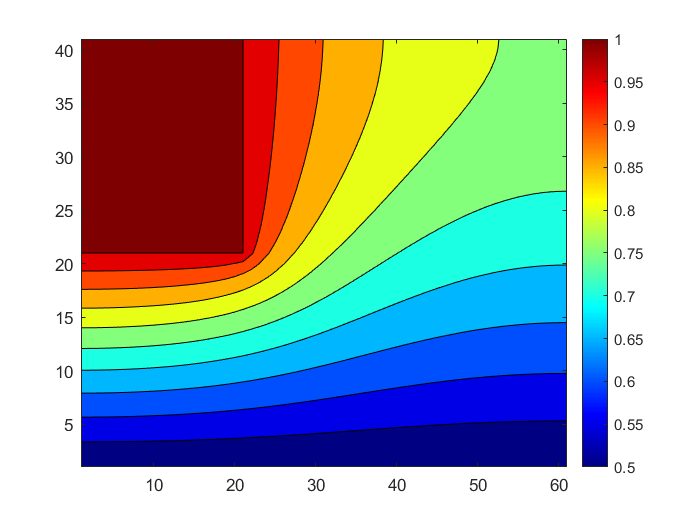

temperature_1 = contourf(T');
colormap jet
colorbar

## Problem 1

Listing this out in a table...

Lambda = [1.5,1.7,1.9,1.95,1.98]';
Iteration = [1737,1004,314,255,633]';
tab1 = table(lambda,Iteration)

Error using table (line 232)
All table variables must have the same number of rows.

## Problem 2

These are the following plots,

For N = 5

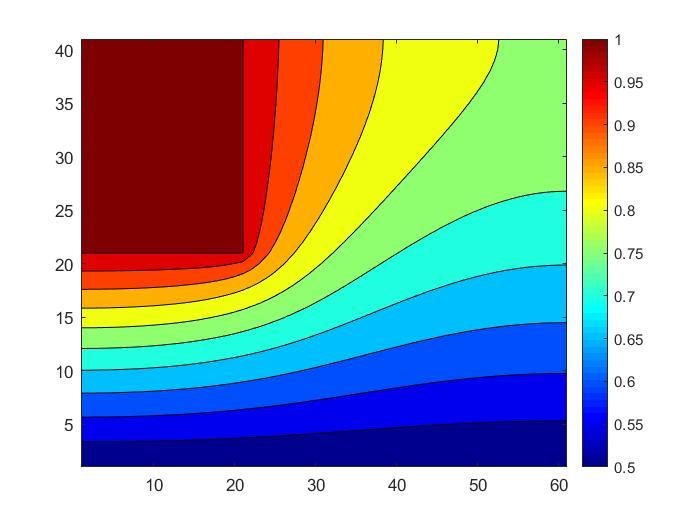

For N = 10

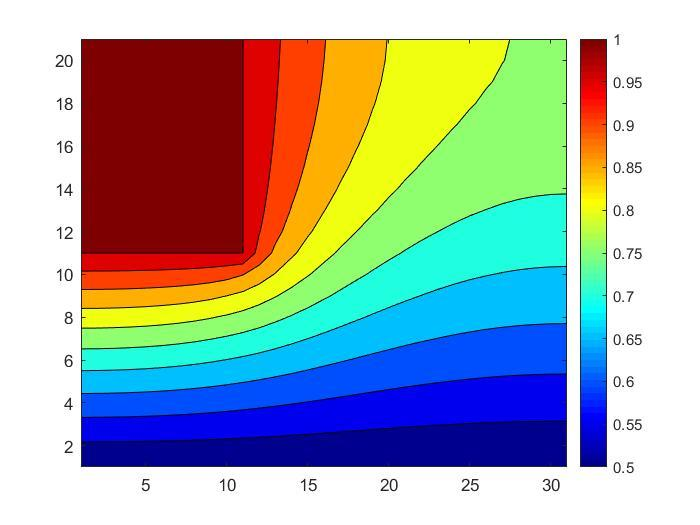

For N = 20

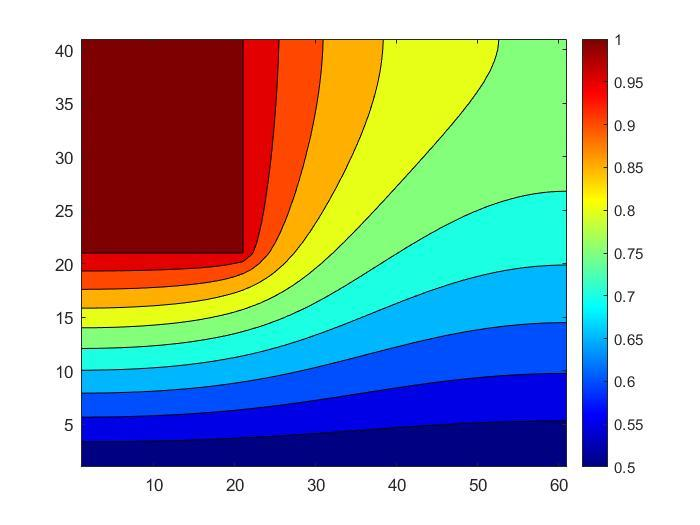

## Problem 3

Obtaining plots

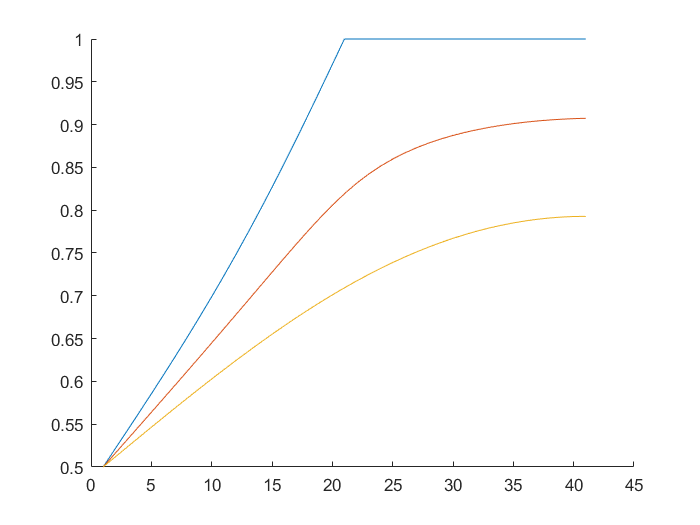

T = T';
figure 
hold on
plot(T(:,1))
plot(T(:,floor(M_r/2)))
plot(T(:,M_r))
axis auto

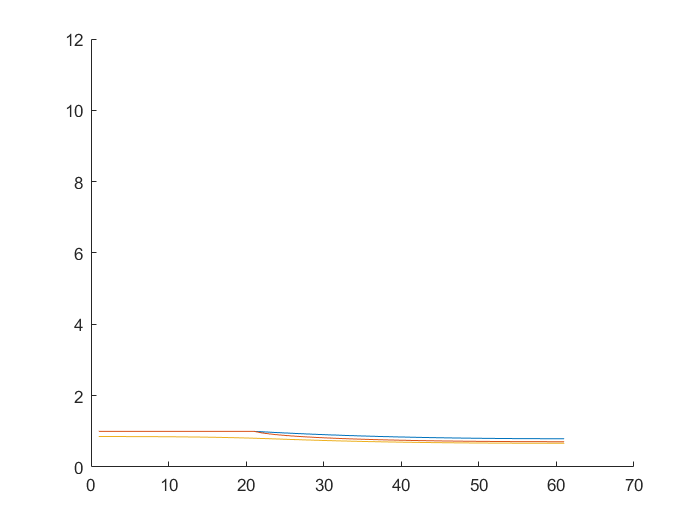


figure
hold on
plot(T(M_z,:))
plot(T(N_z+1,:))
plot(T(floor(3*N_z/4) + 1,:))
plot(floor(N_z/2) + 1)
axis auto

## Problem 4

To calculate the gradient field...

[R_mesh,Z_mesh] = meshgrid(r,z);    %Creates meshgrid
Nr_interp=11;
Nz_interp=11;
ri=linspace(0,3*R,Nr_interp);
zi=linspace(0,2*H,Nz_interp);
[RI,ZI]=meshgrid(ri,zi);

%-- interpolate temparature field (T) on the coarse grid
TI=interp2(R_mesh,Z_mesh,T',RI,ZI);

Error using griddedInterpolant
The grid vectors do not define a grid of points that match the given values.

Error in interp2>makegriddedinterp (line 228)
    F = griddedInterpolant(varargin{:});

Error in interp2 (line 136)
        F = makegriddedinterp(X, Y, V, method,extra


%numerically compute temperature gradient field (qx,qy)
dri = ri(2) - ri(1);                                    % x-mesh size of the coarse grid
dzi = zi(2) - zi(1);                                    % y-mesh size of the coarse grid
[qr,qz] = gradient(TI,dri,dzi);
qr = -qr;
qz = -qz;

%Plotting
figure                              %Creates new figure
hold on
clevel = linspace(0.5,1,15);        %Sets the level of contours for the contour plot
contourf(R_mesh,Z_mesh,T',clevel)   %Plots a contour plot
axis equal                          %Sets the axis equal to one another
xlabel('r');
ylabel('z');
title(strcat('N_{r} = N_{z} =','{ }',num2str(N_r)));
colormap jet
colorbar
quiver(RI,ZI,qr,qz,'k')                     %Creates heat flux arrows on the plot
hold off

